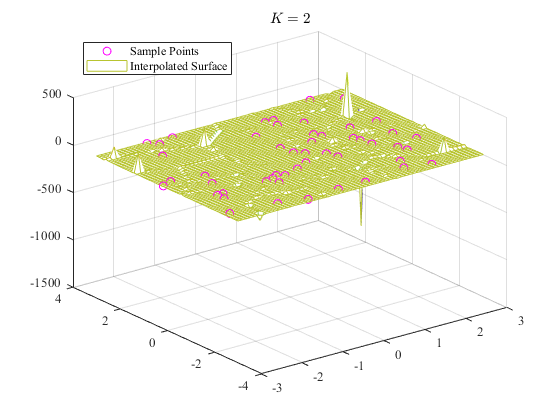

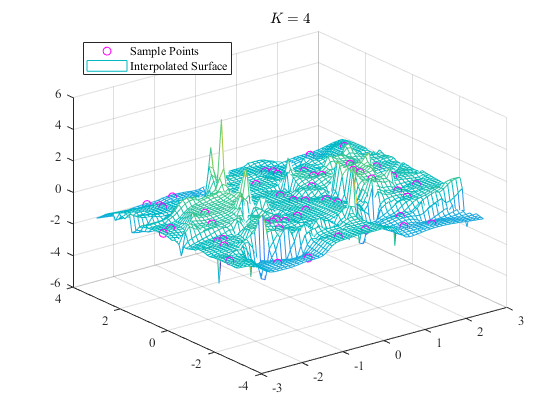

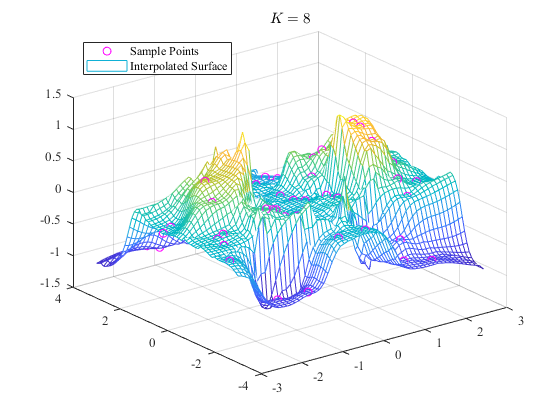

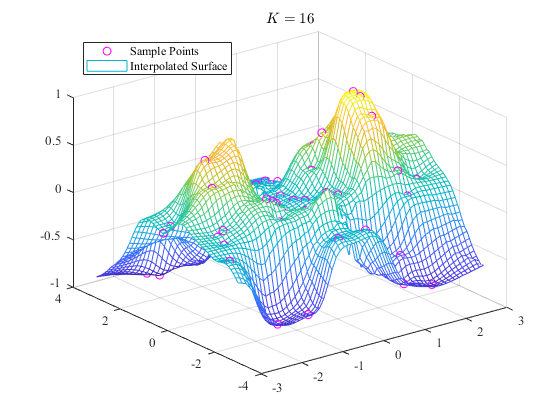

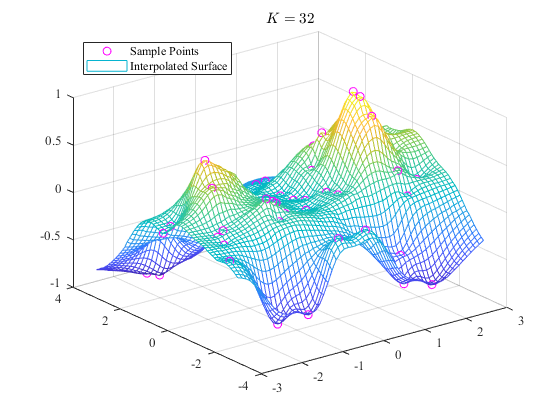

% Create a sample dataset containing 50 random points.
clear all
close all
rng(10) % Initialize the random number generator with a seed of 10
X = -3 + 6*rand(50,1); % Generate random x-coordinates
Y = -3 + 6*rand(50,1); % Generate random y-coordinates
V = sin(X).^4 .* cos(Y); % Compute the corresponding values

% Create a grid of query points.
[xq, yq] = meshgrid(-3:0.1:3);

Ks = [2, 4, 8, 16, 32]; % Define the list of K values for IDWR
for i = 1:length(Ks)
    K = Ks(i);
    vq = IDWR(X, Y, V, xq, yq, K); % Perform Inverse Distance Weighted Regression (IDWR) interpolation
    
    figure
    plot3(X, Y, V, 'mo') % Plot the sample points
    hold on
    mesh(xq, yq, vq) % Plot the interpolated surface
    title(['$K=', num2str(K), '$'], 'interpreter', 'latex') 
    legend('Sample Points', 'Interpolated Surface', 'Location', 'NorthWest') 
    set(gca, 'FontName', 'Times New Roman') 
    grid on 
end

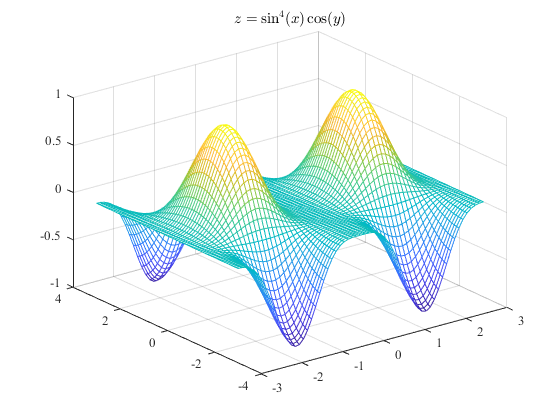


%% Plot the true surface
figure
vq = sin(xq).^4 .* cos(yq); % Compute the true surface values
mesh(xq, yq, vq) % Plot the true surface
title('$z=\sin^{4}(x)\cos(y)$', 'interpreter', 'latex') 
set(gca, 'FontName', 'Times New Roman')
grid on